# Creating and Training a CNN to Classify Traffic Signs

For the Week 1 Project, you will:

- Prepare the traffic signs dataset for training

- Create a simple CNN

- Train the model to classify traffic signs

- Evaluate your trained model on test data

After you have finished, please proceed to the **"Week 1 Project: Classifying Traffic Signs with a Simple CNN" **assessment to answer questions about your results.

## Prepare Your Data for Training

Inside the "Traffic Signs" folder, the data is already separated into Train and Test folders. 

Create an image datastore from the training dataset named `imdsSigns`:

% Select the location of the training data set:
filename = "D:\Workspace\DL for Computer Vision\Data\Traffic Signs\Train\";

% Your code to create a datastore of training images:
imdsTrafficSign = imageDatastore(filename, "IncludeSubfolders", true, "LabelSource","foldernames");


Use 80% of your data for training, leaving the remaining images for validation. Make sure to randomize which images are assigned to the validation set.

[imdsTrain, imdsValidation] = splitEachLabel(imdsTrafficSign, 0.8, "randomized");

tbl = countEachLabel(imdsValidation)

tbl = 9×2 table
         Label         Count
    _______________    _____

    End Speed Limit     20  
    Speed Limit 100     20  
    Speed Limit 120     20  
    Speed Limit 20      20  
    Speed Limit 30      20  
    Speed Limit 50      20  
    Speed Limit 60      20  
    Speed Limit 70      20  
    Speed Limit 80      20  


## Preview the Training Data

Before you dive into building your network architecture, it's worth familiarizing yourself with the images in this data set. 

Run this section several times to preview some of the training data:

img = read(imdsTrafficSign);
size(img)

ans =     34    32     3


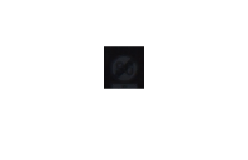

imshow(img)

Notice how many of the images are small, dark, blurry, or otherwise difficult to see. 

All images are in RGB format, with sizes  $m \times n \times 3$, but they have a range of different sizes. Before you can train, you will have to resize these images to match the image input layer.

## Define the Network Architecture

Use the Deep Network Designer App app to create and export a network with the following layers:

- `imageInputLayer`

- `convolution2dLayer`

- `reluLayer`

- `maxPooling2dLayer`

- `fullyConnectedLayer`

- `softmaxLayer`

Make sure you specify the correct `OutputSize` for `fullyConnectedLayer`.

net = dlnetwork;
tempNet = [
    imageInputLayer([227 227 3],"Name","imageinput")
    convolution2dLayer([3 3],32,"Name","conv","Padding","same")
    reluLayer("Name","relu")
    maxPooling2dLayer([5 5],"Name","maxpool","Padding","same")
    fullyConnectedLayer(9,"Name","fc")
    softmaxLayer("Name","softmax")];
net = addLayers(net,tempNet);

% clean up helper variable
clear tempNet;

net = initialize(net);



## Resize Your Training Data

Resize the training and validation data to match the `InputSize` that you set above:

augTrain = augmentedImageDatastore([227 227], imdsTrain);
augVal = augmentedImageDatastore([227 227], imdsValidation);

## Setting the Training Options

Finally, set your training options. You'll investigate training options in more detail later in this course. For now, use the same options you saw in the video:

- Set the solver to `"adam"`

- Include the validation data you set aside earlier

- Set the Shuffle option to `"every-epoch"`

- Set the Plots option to `"training-progress"`

opts = trainingOptions("adam", "ValidationData",augVal, "Shuffle","every-epoch", "Plots","training-progress");

## Train the Network

It's time to train your network! 

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _________    _____    ___________    _________    ____________    ______________
            0        0       00:00:00        0.001                            12.431
            1        1       00:00:00        0.001          12.847                  
           50       10       00:00:13        0.001          3.8222            6.8464
          100       20       00:00:26        0.001          1.2964            5.0312
          150       30       00:00:39        0.001          1.7069            5.3389
Training stopped: Max epochs completed


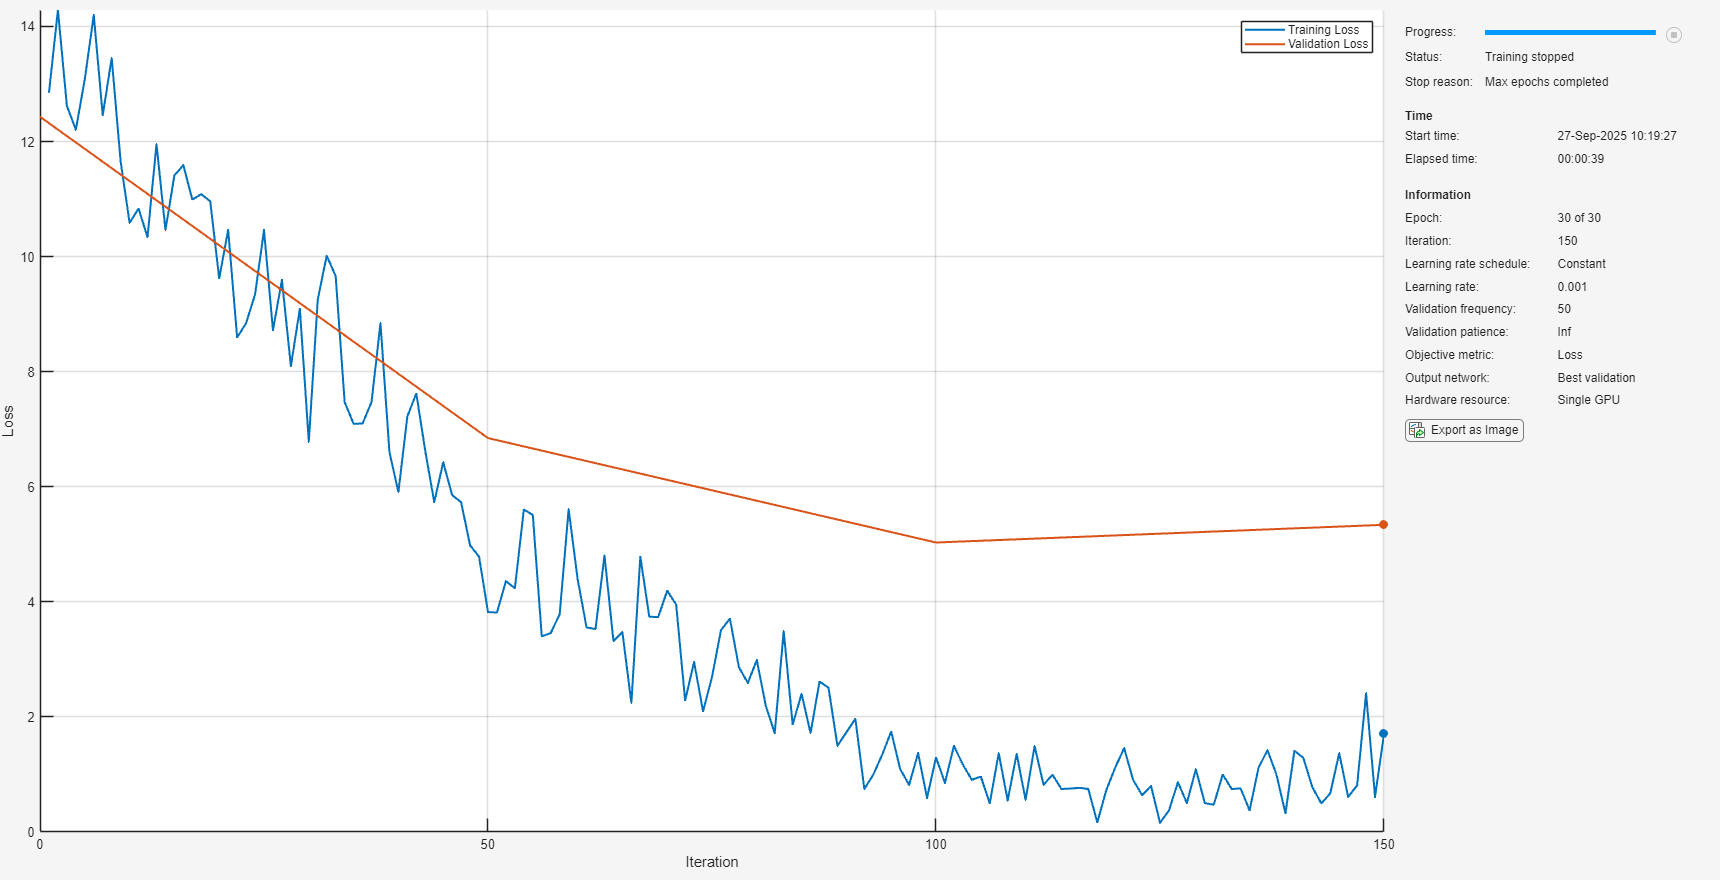

net = trainnet(augTrain, net, "crossentropy", opts);

Training took about 45 minutes on my CPU.

## Performance on Test Data

Once you have trained your network, you should examine its performance on your test data.

Don't forget to resize your images to match the expected input size for your trained network:

filenameTest = "D:\Workspace\DL for Computer Vision\Data\Traffic Signs\Test";
imdsTest = imageDatastore(filenameTest, "IncludeSubfolders",true, "LabelSource","foldernames");
augTest = augmentedImageDatastore([227 227], imdsTest);


Finally, use your test data to evaluate your trained network, including calculating the test accuracy and creating a confusion chart. You may need to click the arrow and open your confusion charts in the figure window to see them well:

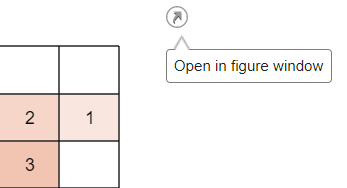

testPreds = minibatchpredict(net, augTest)

testPreds = 288×9 single matrix
     1     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0


classes = categories(imdsTest.Labels);
testPredsClass = scores2label(testPreds, classes)

testPredsClass = 288×1 categorical array
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 
     End Speed Limit 


testAccuracy = nnz(testPredsClass == imdsTest.Labels)/length(testPredsClass)

testAccuracy = 0.6076

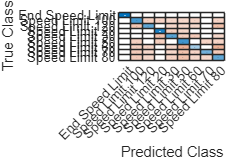

[~, idx] = max(testPreds, [], 2);    % pick highest score class index
classNames = categories(imdsTest.Labels);  % get class names
testPreds = categorical(classNames(idx));  % convert indices to categorical
confusionchart(imdsTest.Labels, testPreds);

While not perfect, this network performs surprisingly well considering the limited data set, the large number of classes, and the relatively simple architecture of your neural network. Later in this course, you will see how to achieve much better accuracy and loss values for this dataset.

Once you have completed this reading, proceed to the "Week 1 Project: Classifying Traffic Signs with a Simple CNN" quiz. You may want to keep this completed live script open as a reference as you answer questions about your results.

*Copyright 2025 The MathWorks, Inc.*